close all
clear
clc

定义符号

syms t x

定义宽为10的矩形脉冲，对其做傅里叶变换

x = heaviside(t)-heaviside(t-10);
Fx = fourier(x);

定义频率采样点，取傅里叶变换在这些采样点上的值

omg = [-3*pi:0.02:3*pi];
Fx1 = double(subs(Fx,'w',omg));

对上述矩形脉冲做拉普拉斯变换

Lx = laplace(x);

定义s平面的采样点，分别由实轴采样和虚轴（频率）采样组合得到

sgm = [0:0.05:1];
re = repmat(sgm,length(omg),1);
im = repmat(omg',1,length(sgm));
s1 = re + 1i*im;

取s平面采样点上的拉普拉斯变换值

Lx1 = double(subs(Lx,'s',s1));

准备绘图

figure, box on, hold on, grid on;

绘制拉普拉斯变换的实部的曲面

surf(sgm,omg,real(Lx1),'LineStyle','none');

绘制傅里叶变换的实部的曲线

plot3(0*omg,omg,real(Fx1),'k','LineWidth',2);
xlabel('\sigma','FontSize',14);
ylabel('\omega','FontSize',14);
zlabel('L(x) & F(x)','FontSize',14);
set(gca,'FontSize',14);
set(gca,'XTick',[0:0.5:1],'YTick',[-2*pi:pi:2*pi]);
set(gca,'YTickLabel',{'-2pi';'-pi';'0';'pi  ';'2pi '});

调整视角

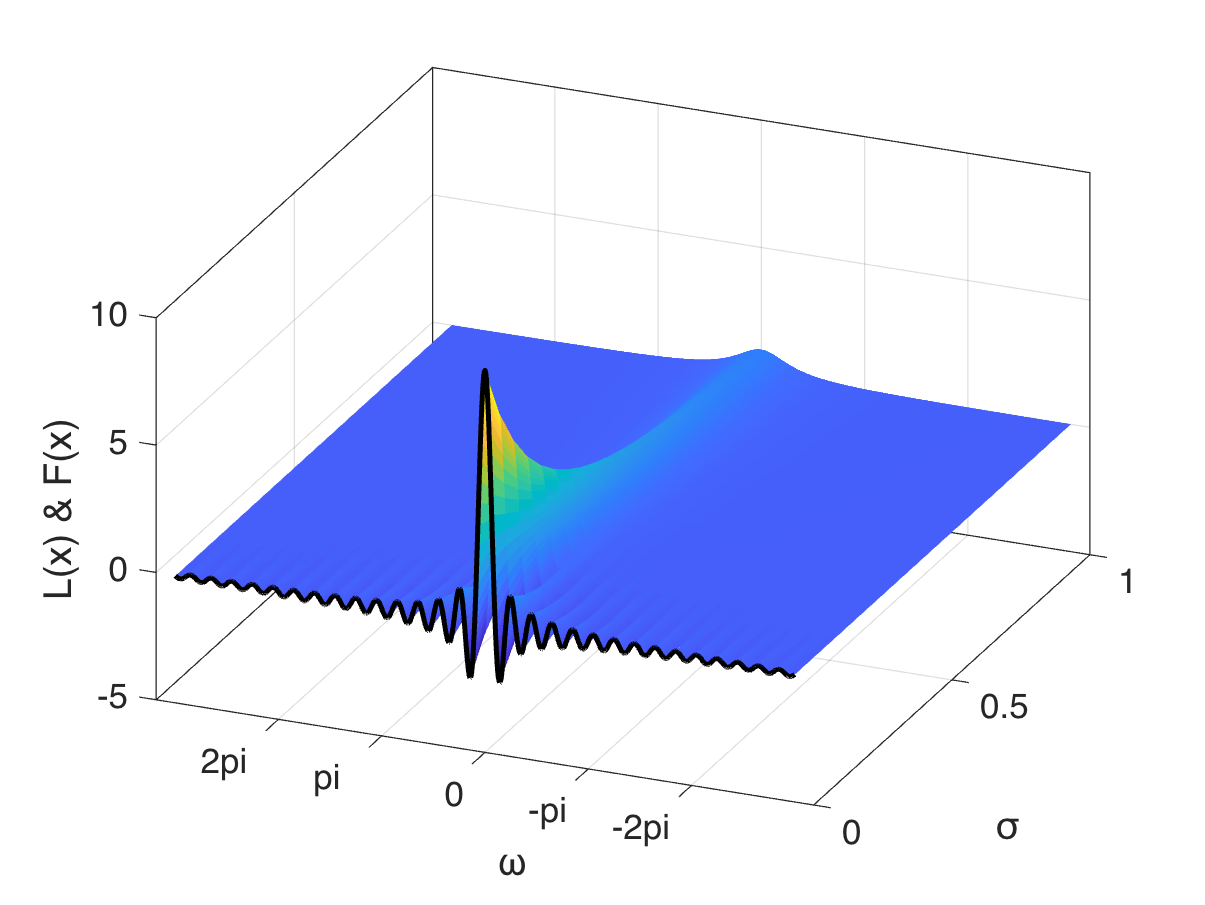

view([-67.2 35.4])